La ecuacion de Bernoulli para un flujo continuo que sale de un tanque, relaciona el flujo volumetrico Q, con la altura h del fluido en el tanque


$$Q={\mathrm{kh}}^a$$


Los siguientes datos relaciona el flujo con el nivel del liquido en el tanque

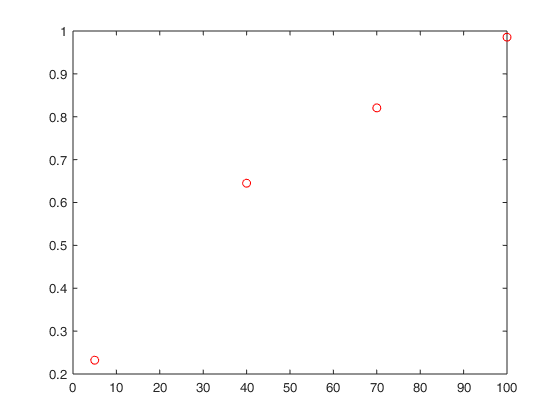

h=[5 40 70 100];
Q=[0.2322 0.6450 0.8207 0.9856];
plot(h,Q,"or")

lh=log(h);lQ=log(Q);
p=polyfit(lh,lQ,1)

p =     0.4816   -2.2317


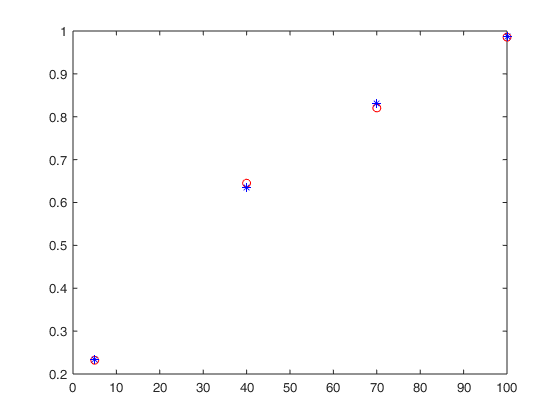

a=p(1);k=exp(p(2));
Qc=k*h.^a;
plot(h,Q,'or',h,Qc,'*b')